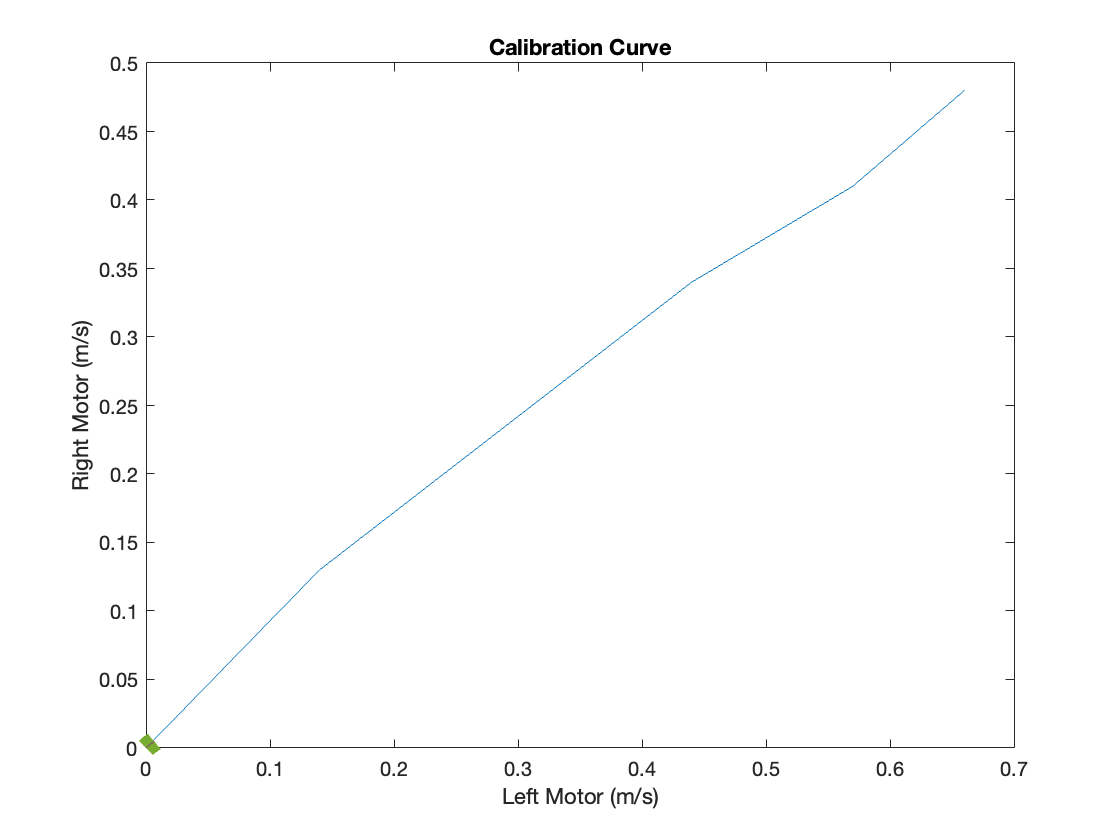

% Checking if motors have same speed

clear
load Data/calibration_first_run.mat

sample_limit = 5;                                               % Max limit of valid data
left_motor = calibration_first_run(1:sample_limit,1) / 100;
right_motor = calibration_first_run(1:sample_limit,2) / 100;

hold on 
title("Motor Check")
xlabel("Left Motor (m/s)")
ylabel("Right Motor (m/s)")
plot(left_motor, right_motor)


p = polyfit(left_motor, right_motor, 1);
 
cali_cruve_slope = p(1);
cali_cruve_y_intercept = p(2);